fisher faces v2

rewrite the beginning bc there are the same number of faces for all the people... maybe the error is there.

clear;

load class_data_test.mat
load class_data_train.mat

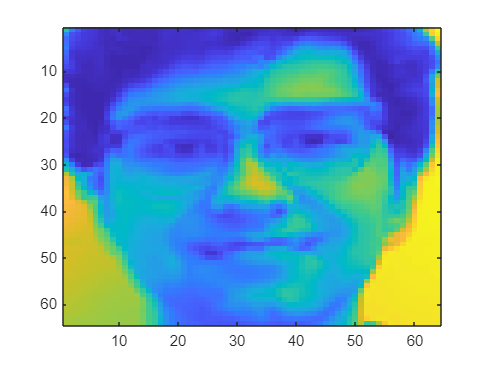

% reshape images to 2d matrix - 4096x356 (4096 pixels, 356 faces)
trainfaces = reshape(grayfaces_train, size(grayfaces_train,1)*size(grayfaces_train,2),size(grayfaces_train,3));

% find the mean of each class - each class is a different subject/person
numclasses = max(subject_train);
meanclass = zeros(4096, numclasses);
temp = zeros(4096,1);
j = 0;

for i = 1:size(trainfaces, 2)
    temp = temp + trainfaces(:,i);
    j = j+1;
    if j == 4
        meanclass(:, subject_train(i)) = temp/j;
        j = 0;
        temp = zeros(4096,1);
    end
end

% making sure meanclass works
testimage = reshape(meanclass(:,4), 64, 64);
imagesc(testimage(:,:))

**Between Class Scatter**

sbetween = zeros(4096, 1);
totalmean = mean(trainfaces, 2);
for i = 1:numclasses
    inside = (meanclass(i,:) - totalmean) * (meanclass(i,:) - totalmean)';
    sbetween = sbetween + 4*inside;
end

**WIthin Class Scatter**

swithin = zeros(4096,1);
for i = 0:numclasses-1
    total = zeros(4096,1);
    for j = 1:4
        k = 4*i + j;
        inside = (trainfaces(:,k)-meanclass(:,i+1))*(trainfaces(:,k)-meanclass(:,i+1))';
        total = total + inside;
    end
    swithin = swithin + total;
end

 k = 10   % number of principal components

k = 10

percent = zeros(356,1);
    % finding principal components
    [w_pca,pca_diag]=eig(cov(trainfaces')); % W_pca
    w_pca = w_pca(:,1:k);
    [w_fld, diag] = eig(w_pca'*sbetween*w_pca, w_pca'*swithin*w_pca); % W_fld
    w_fld = w_fld(:,1:k);
    w_opt = (w_fld'*w_pca');
    w_opt = real(w_opt)'; % Gets rid of imaginary numbers and transposes it

    % prints fisher faces
    % for i = 1: k
    %     figure;
    %     testimage = reshape(w_opt(:,i), 64, 64);
    %     imagesc(testimage(:,:)); colormap('gray');
    % end




    % finding the projection
    projectiontrain = trainfaces'*w_opt;
    testfaces = reshape(grayfaces_test, size(grayfaces_test,1)*size(grayfaces_test,2),size(grayfaces_test,3));
    projectiontest = testfaces'*w_opt;




     % checking each test face against each train face to determine who's face it is
     guess = zeros(size(projectiontest,1),1);
     for test = 1:size(projectiontest,1)
         least = 10000;
         for train = 1:size(projectiontrain,1)
             p = projectiontest(test,:);
             q = projectiontrain(train,:);
             dist = sum(abs(p-q));
             if dist < least
                 least = dist;
                 guess(test) = subject_train(train);
             end
         end
     end
     
     % check how many are right
     numcorrect = 0;
     for i = 1:size(guess,1)
         if guess(i) == subject_test(i)
             numcorrect = numcorrect + 1;
         end
     end
     
     percentcorrect = numcorrect/356;
     


